## Lista 8 - Robótica

import RoboticaBiblioteca.*
printListaManipuladores()

--------------------> Lista de Manipuladores <-----------------------
1 - Manipulador Cartesiano: PPP
   1.1 - Manipulador Pórtico: cartesianos, mas com base em suportes
2 - Manipulador Cilíndrico: RPP
3 - Manipulador Articulados/Antropomórficos: RRR
4 - Manipulador Esféricos/Polares: RRP
5 - Manipulador SCARA: RRP, diferente do esférico, tem três eixos z0,
                       z1 e z2 todos verticais e paralelos


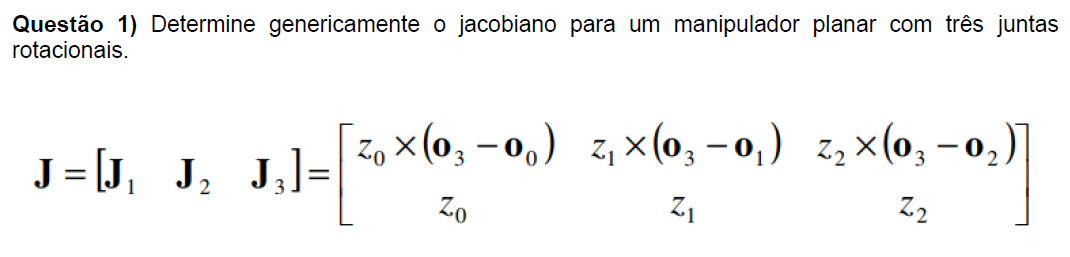

|  link  |   a   | alpha |    d    |    theta   |

| 0 - 1 |  a1  |     0    |    0    |  theta1*  |  R

| 1 - 2 |  a2  |     0    |    0    |  theta2*  |  R

| 1 - 2 |  a3  |     0    |    0    |  theta3*  |  R

syms a1 a2 a3 theta1 theta2 theta3;
DH = [a1 0 0 theta1;
      a2 0 0 theta2;
      a3 0 0 theta3];
[H03, Alc] = MatProgDenavit(DH)

A01 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & a_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & a_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & a_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & a_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$H03 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{3}\right)\,\sigma_{3}-\sin\left(\theta_{3}\right)\,\sigma_{2} & 0 & a_{1}\,\cos\left(\theta_{1}\right)+a_{3}\,\cos\left(\theta_{3}\right)\,\sigma_{2}-a_{3}\,\sin\left(\theta_{3}\right)\,\sigma_{3}+a_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-a_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \cos\left(\theta_{3}\right)\,\sigma_{3}+\sin\left(\theta_{3}\right)\,\sigma_{2} & \sigma_{1} & 0 & a_{1}\,\sin\left(\theta_{1}\right)+a_{3}\,\cos\left(\theta_{3}\right)\,\sigma_{3}+a_{3}\,\sin\left(\theta_{3}\right)\,\sigma_{2}+a_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+a_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{3}\right)\,\sigma_{2}-\sin\left(\theta_{3}\right)\,\sigma_{3}\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{3}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) \end{array}$$

Alc = 1×3 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}


J = jacobiano(Alc,'RRR',false);
J = simplify(J)

$$J = \begin{array}{l} \left(\begin{array}{ccc} -a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-a_{1}\,\sin\left(\theta_{1}\right)-\sigma_{1} & -a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-\sigma_{1} & -\sigma_{1}\\ a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)+\sigma_{2} & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{2} & \sigma_{2}\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=a_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

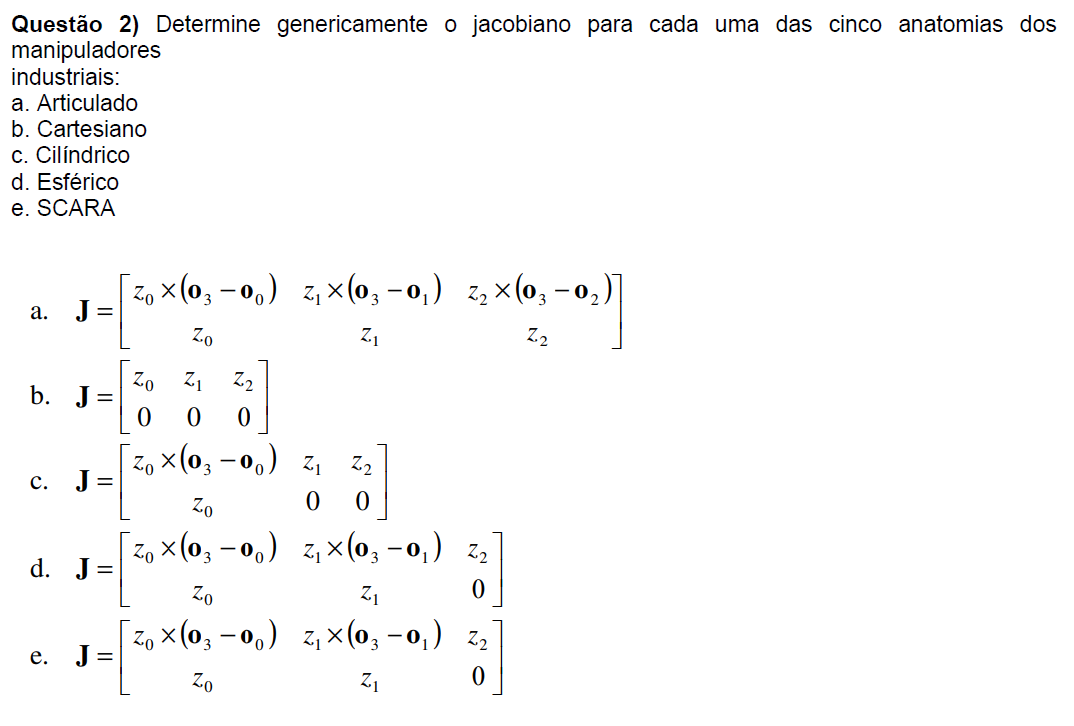

syms a1 a2 a3 alpha1 alpha2 alpha3 d1 d2 d3 theta1 theta2 theta3;
DH = [a1 alpha1 d1 theta1;
      a2 alpha2 d2 theta2;
      a3 alpha3 d3 theta3];
[H06, Alc] = MatProgDenavit(DH);

A01 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\cos\left(\alpha_{1}\right)\,\sin\left(\theta_{1}\right) & \sin\left(\alpha_{1}\right)\,\sin\left(\theta_{1}\right) & a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\alpha_{1}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\alpha_{1}\right)\,\cos\left(\theta_{1}\right) & a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & \sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\cos\left(\alpha_{2}\right)\,\sin\left(\theta_{2}\right) & \sin\left(\alpha_{2}\right)\,\sin\left(\theta_{2}\right) & a_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\alpha_{2}\right)\,\cos\left(\theta_{2}\right) & -\sin\left(\alpha_{2}\right)\,\cos\left(\theta_{2}\right) & a_{2}\,\sin\left(\theta_{2}\right)\\ 0 & \sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\cos\left(\alpha_{3}\right)\,\sin\left(\theta_{3}\right) & \sin\left(\alpha_{3}\right)\,\sin\left(\theta_{3}\right) & a_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\alpha_{3}\right)\,\cos\left(\theta_{3}\right) & -\sin\left(\alpha_{3}\right)\,\cos\left(\theta_{3}\right) & a_{3}\,\sin\left(\theta_{3}\right)\\ 0 & \sin\left(\alpha_{3}\right) & \cos\left(\alpha_{3}\right) & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Letra A: Articulado)
J = simplify(jacobiano(Alc,'RRR',false))

% Letra B: Cartesiano)
J = simplify(jacobiano(Alc,'PPP',false))

$$J = \left(\begin{array}{ccc} 0 & \sin\left(\alpha_{1}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\alpha_{2}\right)\,\sin\left(\alpha_{1}\right)\,\sin\left(\theta_{1}\right)+\sin\left(\alpha_{2}\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\alpha_{1}\right)\,\sin\left(\alpha_{2}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\sin\left(\alpha_{1}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\alpha_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\alpha_{2}\right)\,\sin\left(\alpha_{1}\right)\,\cos\left(\theta_{1}\right)-\cos\left(\alpha_{1}\right)\,\sin\left(\alpha_{2}\right)\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ 1 & \cos\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right)\,\cos\left(\alpha_{2}\right)-\sin\left(\alpha_{1}\right)\,\sin\left(\alpha_{2}\right)\,\cos\left(\theta_{2}\right)\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

% Letra C: Cilíndrico)
J = simplify(jacobiano(Alc,'RPP',false))

% Letra D: Esférico)
J = simplify(jacobiano(Alc,'RRP',false))

% Letra E: SCARA)

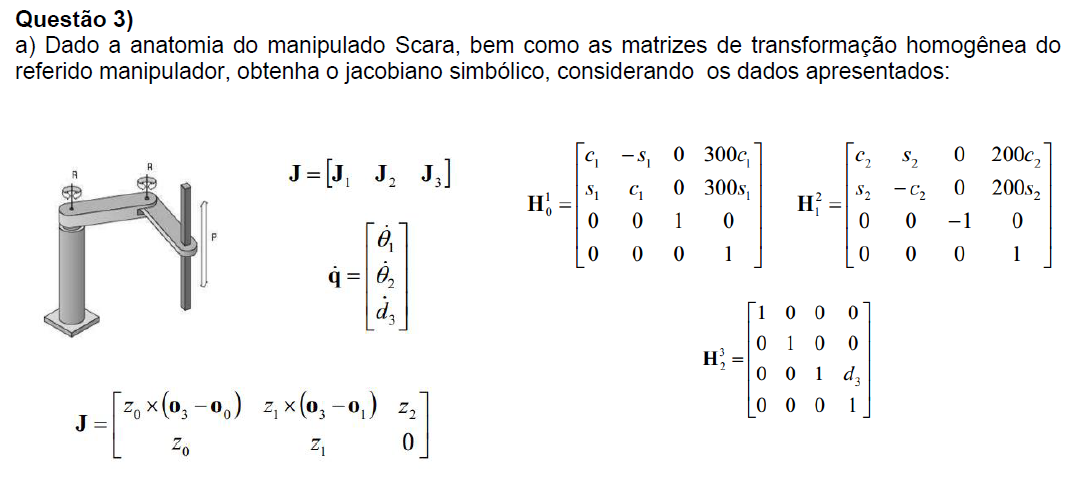

syms theta1 theta2 theta3 d3;
Alc = cell(0,0);
Alc{1} = [cosd(theta1) -sind(theta1) 0 300*cosd(theta1);
          sind(theta1) cosd(theta1) 0 300*sind(theta1);
          0 0 1 0;
          0 0 0 1];
Alc{2} = [cosd(theta2) sind(theta2) 0 200*cosd(theta2);
          sind(theta2) -cosd(theta2) 0 200*sind(theta2);
          0 0 -1 0;
          0 0 0 1];
Alc{3} = [1 0 0 0;
          0 1 0 0;
          0 0 1 d3;
          0 0 0 1];
J = jacobiano(Alc,'RRP',true)

Z0 = 
     0
     0
     1

O0 = 
     0
     0
     0

Z1 = 


$$\left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

O1 = 


$$\left(\begin{array}{c} 300\,\cos\left(\frac{\pi \,\theta_{1}}{180}\right)\\ 300\,\sin\left(\frac{\pi \,\theta_{1}}{180}\right)\\ 0 \end{array}\right)$$

Z2 = 


$$\left(\begin{array}{c} 0\\ 0\\ -1 \end{array}\right)$$

O3 = 


$$\begin{array}{l} \left(\begin{array}{c} 300\,\sigma_{2}+200\,\sigma_{2}\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)-200\,\sigma_{1}\,\sin\left(\frac{\pi \,\theta_{2}}{180}\right)\\ 300\,\sigma_{1}+200\,\sigma_{2}\,\sin\left(\frac{\pi \,\theta_{2}}{180}\right)+200\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)\,\sigma_{1}\\ -d_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\theta_{1}}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,\theta_{1}}{180}\right) \end{array}$$

$$J = \begin{array}{l} \left(\begin{array}{ccc} -300\,\sin\left(\frac{\pi \,\theta_{1}}{180}\right)-\sigma_{3}-\sigma_{2} & -\sigma_{3}-\sigma_{2} & 0\\ 300\,\cos\left(\frac{\pi \,\theta_{1}}{180}\right)+\sigma_{4}-\sigma_{1} & \sigma_{4}-\sigma_{1} & 0\\ 0 & 0 & -1\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=200\,\sin\left(\frac{\pi \,\theta_{1}}{180}\right)\,\sin\left(\frac{\pi \,\theta_{2}}{180}\right)\\ \sigma_{2}=200\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)\,\sin\left(\frac{\pi \,\theta_{1}}{180}\right)\\ \sigma_{3}=200\,\cos\left(\frac{\pi \,\theta_{1}}{180}\right)\,\sin\left(\frac{\pi \,\theta_{2}}{180}\right)\\ \sigma_{4}=200\,\cos\left(\frac{\pi \,\theta_{1}}{180}\right)\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right) \end{array}$$

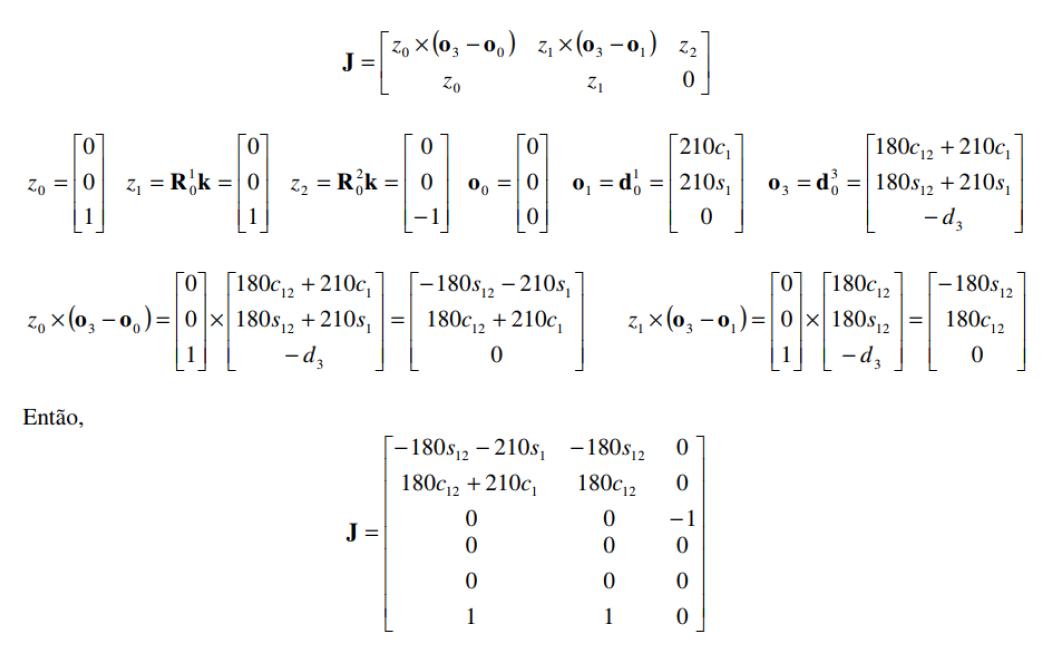

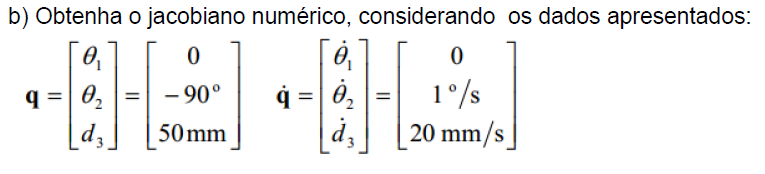

theta1 = 0;
theta2 = -90;
d3 = 50;

q = [0; 1; 20];

Alc = cell(0,0);
Alc{1} = [cosd(theta1) -sind(theta1) 0 300*cosd(theta1);
          sind(theta1) cosd(theta1) 0 300*sind(theta1);
          0 0 1 0;
          0 0 0 1];
Alc{2} = [cosd(theta2) sind(theta2) 0 200*cosd(theta2);
          sind(theta2) -cosd(theta2) 0 200*sind(theta2);
          0 0 -1 0;
          0 0 0 1];
Alc{3} = [1 0 0 0;
          0 1 0 0;
          0 0 1 d3;
          0 0 0 1];
[Velocidade, J] = velJacob(Alc, q, 'RRP', true)

Z0 = 
     0
     0
     1

O0 = 
     0
     0
     0

Z1 = 
     0
     0
     1

O1 = 
   300
     0
     0

Z2 = 
     0
     0
    -1

O3 = 
   300
  -200
   -50



Velocidade =    200
     0
   -20
     0
     0
     1


J =    200   200     0
   300     0     0
     0     0    -1
     0     0     0
     0     0     0
     1     1     0


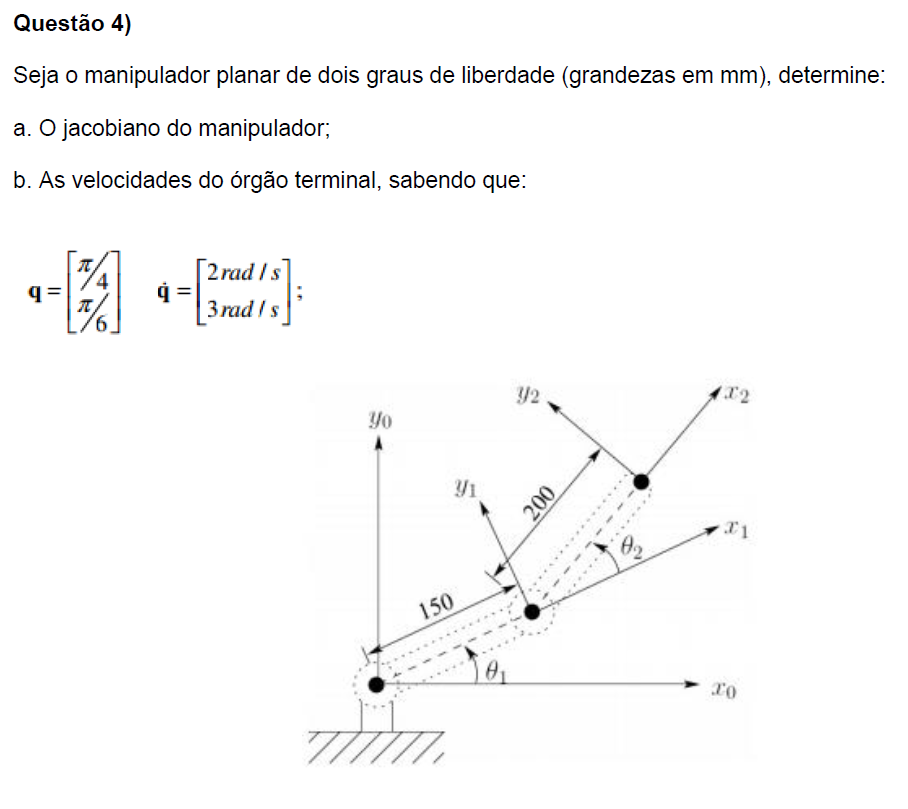

|  link  |   a   | alpha |    d    |    theta   |

| 0 - 1 |  150  |     0    |    0    |  theta1*  |  R

| 1 - 2 |  200  |     0    |    0    |  theta2*  |  R

theta1 = 180/4;
theta2 = 180/6;

q = [2; 3];

DH = [150 0 0 theta1;
      200 0 0 theta2];
[H02, Alc] = MatProgDenavit(DH)

A01 = 
    0.7071   -0.7071         0  106.0660
    0.7071    0.7071         0  106.0660
         0         0    1.0000         0
         0         0         0    1.0000

A12 = 
    0.8660   -0.5000         0  173.2051
    0.5000    0.8660         0  100.0000
         0         0    1.0000         0
         0         0         0    1.0000



H02 =     0.2588   -0.9659         0  157.8298
    0.9659    0.2588         0  299.2512
         0         0    1.0000         0
         0         0         0    1.0000


Alc = 1×2 cell array
    {4×4 double}    {4×4 double}


[Velocidade, J] = velJacob(Alc,q,'RR',true)

Z0 = 
     0
     0
     1

O0 = 
     0
     0
     0

Z1 = 
     0
     0
     1

O1 = 
  106.0660
  106.0660
         0

O2 = 
  157.8298
  299.2512
         0



Velocidade = 	1.0e+03 *

   -1.1781
    0.4710
         0
         0
         0
    0.0050


J =  -299.2512 -193.1852
  157.8298   51.7638
         0         0
         0         0
         0         0
    1.0000    1.0000


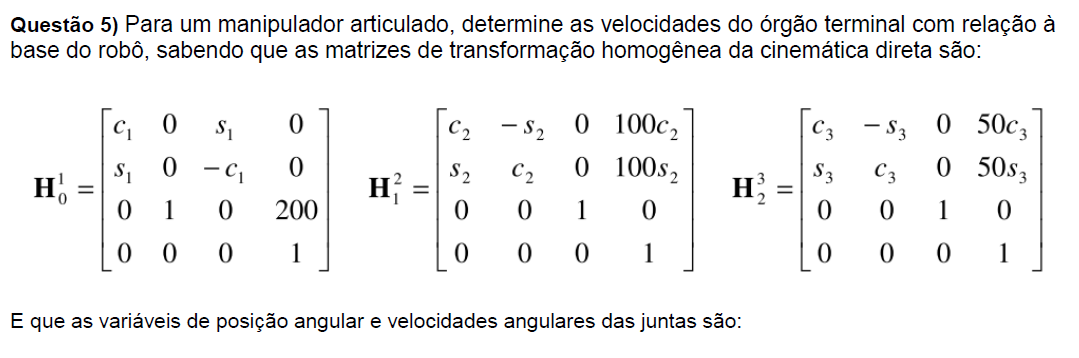

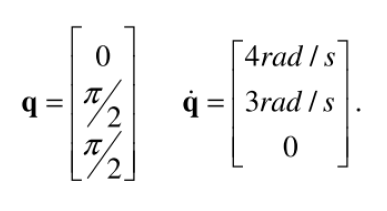

theta1 = 0;
theta2 = 180/2;
theta3 = 180/2;

q = [4; 3; 0];

Alc = cell(0,0);
Alc{1} = [cosd(theta1) 0 sind(theta1) 0;
          sind(theta1) 0 -cosd(theta1) 0;
          0 1 0 200;
          0 0 0 1];
Alc{2} = [cosd(theta2) -sind(theta2) 0 100*cosd(theta2);
          sind(theta2) cosd(theta2) 0 100*sind(theta2);
          0 0 1 0;
          0 0 0 1];
Alc{3} = [cosd(theta3) -sind(theta3) 0 50*cosd(theta3);
          sind(theta3) cosd(theta3) 0 50*sind(theta3);
          0 0 1 0;
          0 0 0 1];

[Velocidade, J] = velJacob(Alc,q,'RRR',true)

Z0 = 
     0
     0
     1

O0 = 
     0
     0
     0

Z1 = 
     0
    -1
     0

O1 = 
     0
     0
   200

Z2 = 
     0
    -1
     0

O2 = 
     0
     0
   300

O3 = 
   -50
     0
   300



Velocidade =   -300
  -200
  -150
     0
    -3
     4


J =      0  -100     0
   -50     0     0
     0   -50   -50
     0     0     0
     0    -1    -1
     1     0     0


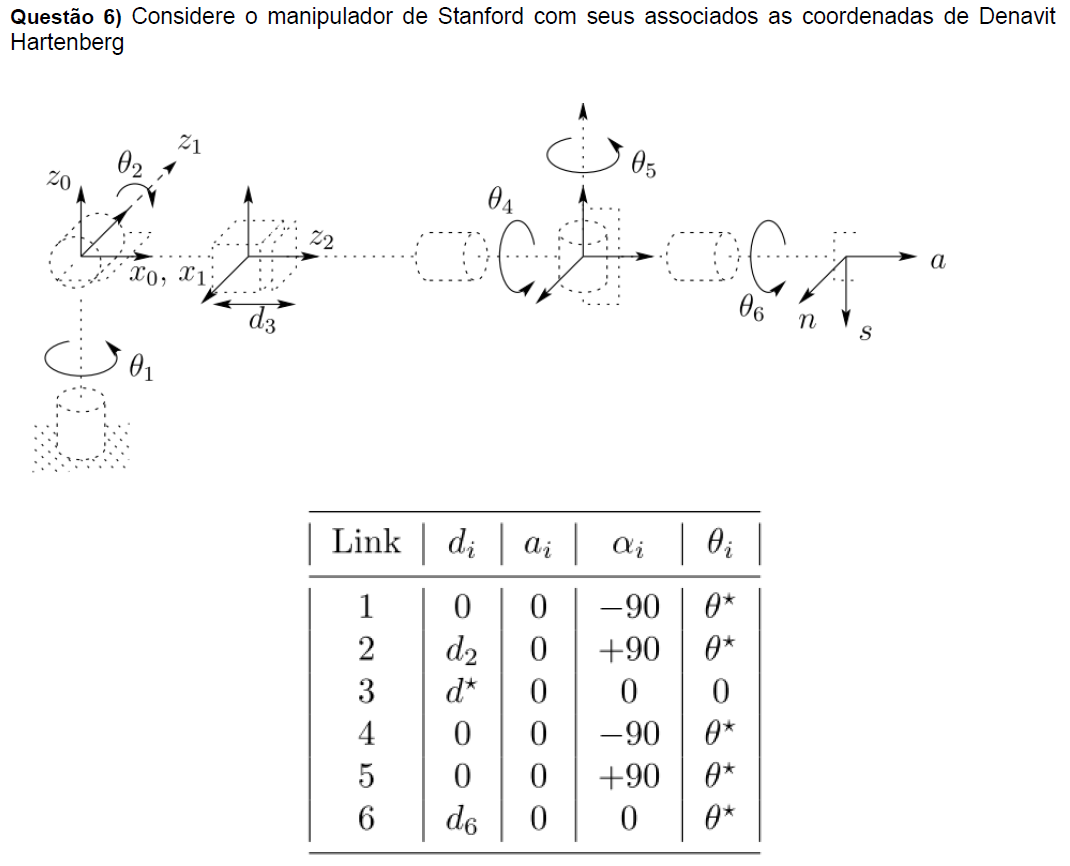

syms d2 d3 d6 theta1 theta2 theta4 theta5 theta6;
DH = [0 -90 0 theta1;
      0 +90 d2 theta2;
      0 0 d3 0;
      0 -90 0 theta4;
      0 +90 0 theta5;
      0 0 d6 theta6];
[H06, Alc] = MatProgDenavit(DH);

A01 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\cos\left(90\right)\,\sin\left(\theta_{1}\right) & -\sin\left(90\right)\,\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & \cos\left(90\right)\,\cos\left(\theta_{1}\right) & \sin\left(90\right)\,\cos\left(\theta_{1}\right) & 0\\ 0 & -\sin\left(90\right) & \cos\left(90\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\cos\left(90\right)\,\sin\left(\theta_{2}\right) & \sin\left(90\right)\,\sin\left(\theta_{2}\right) & 0\\ \sin\left(\theta_{2}\right) & \cos\left(90\right)\,\cos\left(\theta_{2}\right) & -\sin\left(90\right)\,\cos\left(\theta_{2}\right) & 0\\ 0 & \sin\left(90\right) & \cos\left(90\right) & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = 


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A34 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\cos\left(90\right)\,\sin\left(\theta_{4}\right) & -\sin\left(90\right)\,\sin\left(\theta_{4}\right) & 0\\ \sin\left(\theta_{4}\right) & \cos\left(90\right)\,\cos\left(\theta_{4}\right) & \sin\left(90\right)\,\cos\left(\theta_{4}\right) & 0\\ 0 & -\sin\left(90\right) & \cos\left(90\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A45 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & -\cos\left(90\right)\,\sin\left(\theta_{5}\right) & \sin\left(90\right)\,\sin\left(\theta_{5}\right) & 0\\ \sin\left(\theta_{5}\right) & \cos\left(90\right)\,\cos\left(\theta_{5}\right) & -\sin\left(90\right)\,\cos\left(\theta_{5}\right) & 0\\ 0 & \sin\left(90\right) & \cos\left(90\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A56 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0 & 0\\ \sin\left(\theta_{6}\right) & \cos\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 1 & d_{6}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

J = simplify(jacobiano(Alc,'RRRRRR',true))

Z0 = 
     0
     0
     1

O0 = 
     0
     0
     0

Z1 = 


$$\left(\begin{array}{c} -\sin\left(90\right)\,\sin\left(\theta_{1}\right)\\ \sin\left(90\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(90\right) \end{array}\right)$$

O1 = 


$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Z2 = 


$$\left(\begin{array}{c} \sin\left(90\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(90\right)\,\sin\left(90\right)\,\sin\left(\theta_{1}\right)+\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)+\sin\left(90\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ {\sin\left(90\right)}^{2}\,\cos\left(\theta_{2}\right)+{\cos\left(90\right)}^{2} \end{array}\right)$$

O2 = 


$$\left(\begin{array}{c} -d_{2}\,\sin\left(90\right)\,\sin\left(\theta_{1}\right)\\ d_{2}\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)\\ d_{2}\,\cos\left(90\right) \end{array}\right)$$

Z3 = 


$$\left(\begin{array}{c} \sin\left(90\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(90\right)\,\sin\left(90\right)\,\sin\left(\theta_{1}\right)+\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)+\sin\left(90\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ {\sin\left(90\right)}^{2}\,\cos\left(\theta_{2}\right)+{\cos\left(90\right)}^{2} \end{array}\right)$$

O3 = 


$$\left(\begin{array}{c} d_{3}\,\left(\sin\left(90\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(90\right)\,\sin\left(90\right)\,\sin\left(\theta_{1}\right)+\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)-d_{2}\,\sin\left(90\right)\,\sin\left(\theta_{1}\right)\\ d_{3}\,\left(\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)+\sin\left(90\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\right)+d_{2}\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)\\ d_{2}\,\cos\left(90\right)+d_{3}\,\left({\sin\left(90\right)}^{2}\,\cos\left(\theta_{2}\right)+{\cos\left(90\right)}^{2}\right) \end{array}\right)$$

Z4 = 


$$\begin{array}{l} \left(\begin{array}{c} \cos\left(90\right)\,\left(\sin\left(90\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(90\right)\,\sin\left(90\right)\,\sin\left(\theta_{1}\right)+\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)-\sin\left(90\right)\,\cos\left(\theta_{4}\right)\,\left({\sin\left(90\right)}^{2}\,\sin\left(\theta_{1}\right)+\sigma_{2}+{\cos\left(90\right)}^{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)-\sin\left(90\right)\,\sin\left(\theta_{4}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sigma_{1}\right)\\ \cos\left(90\right)\,\left(\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)+\sin\left(90\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\right)+\sin\left(90\right)\,\cos\left(\theta_{4}\right)\,\left({\sin\left(90\right)}^{2}\,\cos\left(\theta_{1}\right)-\sigma_{1}+{\cos\left(90\right)}^{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\right)-\sin\left(90\right)\,\sin\left(\theta_{4}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)+\sigma_{2}\right)\\ \cos\left(90\right)\,\left({\sin\left(90\right)}^{2}\,\cos\left(\theta_{2}\right)+{\cos\left(90\right)}^{2}\right)+{\sin\left(90\right)}^{2}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{4}\right)+\sin\left(90\right)\,\cos\left(\theta_{4}\right)\,\left(\cos\left(90\right)\,\sin\left(90\right)-\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{2}\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(90\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\cos\left(90\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

O4 = 


$$\left(\begin{array}{c} d_{3}\,\left(\sin\left(90\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(90\right)\,\sin\left(90\right)\,\sin\left(\theta_{1}\right)+\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)-d_{2}\,\sin\left(90\right)\,\sin\left(\theta_{1}\right)\\ d_{3}\,\left(\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)+\sin\left(90\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\right)+d_{2}\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)\\ d_{2}\,\cos\left(90\right)+d_{3}\,\left({\sin\left(90\right)}^{2}\,\cos\left(\theta_{2}\right)+{\cos\left(90\right)}^{2}\right) \end{array}\right)$$

Z5 = 


O5 = 


$$\left(\begin{array}{c} d_{3}\,\left(\sin\left(90\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(90\right)\,\sin\left(90\right)\,\sin\left(\theta_{1}\right)+\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)-d_{2}\,\sin\left(90\right)\,\sin\left(\theta_{1}\right)\\ d_{3}\,\left(\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)+\sin\left(90\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(90\right)\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\right)+d_{2}\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)\\ d_{2}\,\cos\left(90\right)+d_{3}\,\left({\sin\left(90\right)}^{2}\,\cos\left(\theta_{2}\right)+{\cos\left(90\right)}^{2}\right) \end{array}\right)$$

O6 = 
